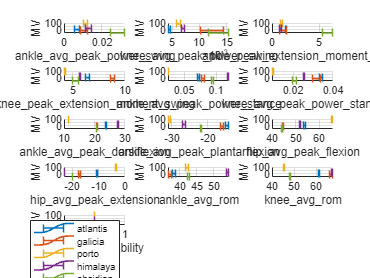

figure('name', 'MV v. Descriptors')
mvstruct = loadMV();
[n_desc, ~] = size(func_names);
phases = ["swing", "stance", "whole"];

subjectnames = fields(packed_data);
n_subj = length(subjectnames);

plot_width = 5;
plot_height = floor(n_desc/plot_width) + 1;

all_subj_desc = double.empty(0);

for s = 1:n_subj
    subjectname = subjectnames{s};

    plot_pos = 0;

    for p = 1:length(phases)
        desc_name_field = "descriptor_names_" + phases(p);
        desc_field = "descriptors_" + phases(p);
        
        desc = packed_data.(subjectname).(desc_field{1});
        desc = desc{1};

        desc_names = packed_data.(subjectname).(desc_name_field{1}){1};
    
        [d, n] = size(desc);
        desc_mean = mean(desc, 2);
        desc_stderr = std(desc, 0, 2) / sqrt(n);
    
        all_subj_desc = [all_subj_desc; desc_mean];

        mvval = str2double(mvstruct.(subjectname)(1));
    
        for j = 1:d
            subplot(plot_width, plot_height, plot_pos + j)
            hold on
            grid on
            errorbar(desc_mean(j), mvval, desc_stderr(j), "horizontal", "LineWidth", 1.3)
    
            xlabel(desc_names{j}, "Interpreter", "none")
            ylabel("MV")
        end

        plot_pos = plot_pos + d;
    end
end
legend(subjectnames, "Interpreter", "none")


all_subj_desc = reshape(all_subj_desc, [n_desc, n_subj]);